# EchoServer Live Script 2 - Speaker Calibration

16 Mar 2022

Run EchoServer 3 and connect the Android clients first.

## 0.1 Basic settings

% Ctrl + Enter to run each section

freq = [14240.625, 14700.   , 15159.375, 15618.75 , 16078.125, 16537.5  ,...
        16996.875, 17456.25 , 17915.625, 18375.   , 18834.375, 19293.75];
fs = 44100;

% high pass filter
fc = 10000;
[b,a] = butter(5, fc/(fs/2), 'high');

% device id
mi6 = 1;
motoz = 2;
pixel4 = 3;

## 0.2 Set up calibrator

Or you can manually mute Mi 6

#### Set to device 1: Mi 6

device = mi6;
disp("[I] Current device: 1 (Mi 6).")

[I] Current device: 1 (Mi 6).


#### Chirp 0: mute

sig_str = sprintf('%f,', zeros(1,4000));
sig_str = sig_str(1:end-1);

#### Send chirp to selected device

writeline(server{device}, sig_str)

## 0.3 Initialize weights

weights_2 = [   1.0         1.0         1.0
                1.0         1.0         1.0
                1.0         1.0         1.0 
                1.0         1.0         1.0
            ];
weights_3 = [   1.0         1.0         1.0
                1.0         1.0         1.0
                1.0         1.0         1.0 
                1.0         1.0         1.0
            ];

## 1.1 Set up source speaker

#### Set to device 2: Moto Z

device = motoz;
disp("[I] Current device: 2 (Moto Z).")

[I] Current device: 2 (Moto Z).


#### Chirp 2: step tones

sig_len = 41*12;
chirp = zeros(1, sig_len);
weights = weights_2;
for i = 1:sig_len
    j = ceil(i/41);
    phase = 2 * pi * freq(j) * i / fs;
    chirp(i) = weights(j) * sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

#### Send chirp to selected device

writeline(server{device}, sig_str)
pause(2)

## 1.2 Play on source speaker, record on calibrator mic

writeline(server{mi6}, "Play.") % record
writeline(server{motoz}, "Play.")
pause(5)
writeline(server{motoz}, "Play.") % stop
writeline(server{mi6}, "Play.")

## 1.3 Plot source speaker data

Check on the available chunks

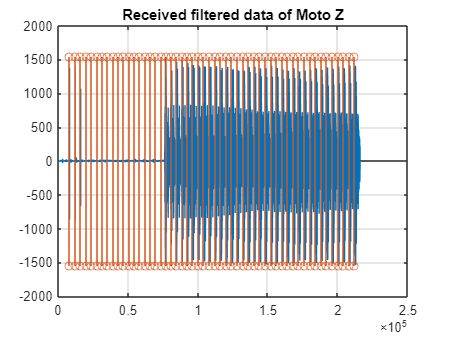

device = mi6;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Moto Z")
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

## 1.4 STFT spectrogram of chirp (speaker of device 2: Moto Z)

r = 6 : start_l - 1;

Kindly select the chunks

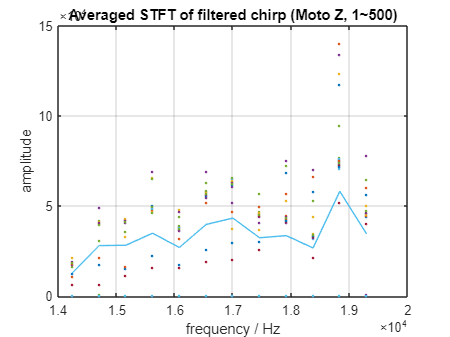

device = mi6;
ss_spec_mean = zeros(12, 9);
ss_amp_mean = zeros(length(freq), 1);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 500 - 1;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f - 1,:); % end is included in MATLAB
    S = abs(ss) / max(max(abs(ss)));
    I = mat2gray(S);

%     figure
%     imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%     xlabel('distance / m'); ylabel('frequency / kHz');
%     % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%     % xlabel('time / ms'); ylabel('frequency / kHz');
% 
%     title("Spectrogram (STFT) of Filtered Signal (550~2919)")
%     set(gca, 'YDir', 'normal');
%     colormap('hot')
    
    ss_sum = sum(abs(ss), 2);
    plot(freq, ss_sum, '.')
    title("Averaged STFT of filtered chirp (Moto Z, 1~500)")
    xlabel("frequency / Hz"); ylabel("amplitude")
    hold on
    grid on

    ss_amp_mean = ss_amp_mean + ss_sum;
    ss_spec_mean = ss_spec_mean + abs(ss);
end
hold on
plot(freq, ss_amp_mean / length(r))

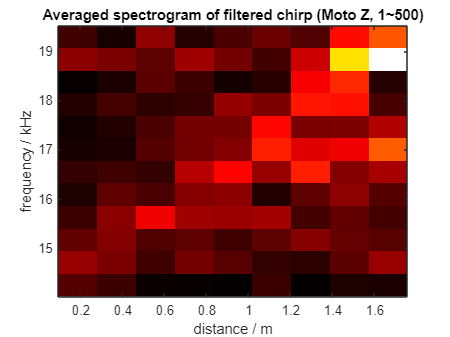


figure
S = abs(ss_spec_mean) / max(max(abs(ss_spec_mean)));
I = mat2gray(S);
imagesc(tt * 170, ff / 1000, I); % distance as x-axis
xlabel('distance / m'); ylabel('frequency / kHz');
% imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% xlabel('time / ms'); ylabel('frequency / kHz');

title("Averaged spectrogram of filtered chirp (Moto Z, 1~500)")
set(gca, 'YDir', 'normal');
colormap('hot')


frc_2 = ss_amp_mean / length(r);

#### Compare frc 2 and 3

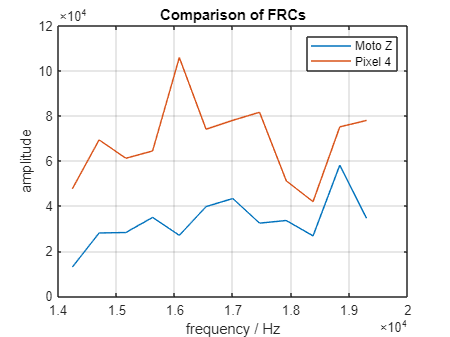

figure
plot(freq, frc_2)
hold on
grid on
plot(freq, frc_3)
title("Comparison of FRCs")
xlabel("frequency / Hz"); ylabel("amplitude")
legend("Moto Z", "Pixel 4")

## 2.1 Set up target speaker

#### Set to device 3: Pixel 4

device = pixel4;
disp("[I] Current device: 3 (Pixel 4).")

[I] Current device: 3 (Pixel 4).


#### Chirp 2: step tones

sig_len = 41*12;
chirp = zeros(1, sig_len);
weights = weights_3;
for i = 1:sig_len
    j = ceil(i/41);
    phase = 2 * pi * freq(j) * i / fs;
    chirp(i) = weights(j) * sin(phase);
end

sig_str = sprintf('%f,', chirp);
sig_str = sig_str(1:end-1);

#### Send chirp to selected device

writeline(server{device}, sig_str)
pause(2)

## 2.2 Play on target speaker, rec1ord on calibrator mic

writeline(server{mi6}, "Play.") % record
writeline(server{pixel4}, "Play.")
pause(5)
writeline(server{pixel4}, "Play.") % stop
writeline(server{mi6}, "Play.")

## 2.3 Plot target speaker data

Check on the available chunks

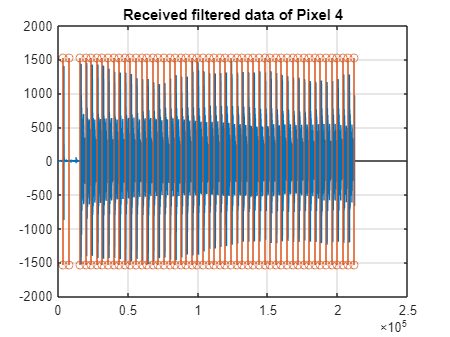

device = mi6;
sig_plot = data_filtered{device};
figure
plot(sig_plot)
title("Received filtered data of Pixel 4")
hold on
grid on
start_x = [start_list{device}, start_list{device}];
start_l = length(start_list{device});
start_y = max(abs(sig_plot)) * [ones(1, start_l), -ones(1, start_l)];
stem(start_x, start_y)
hold off

## 2.4 STFT spectrogram of chirp (speaker of device 3: Pixel 4)

r = 6 : start_l - 1;

Kindly select the chunks

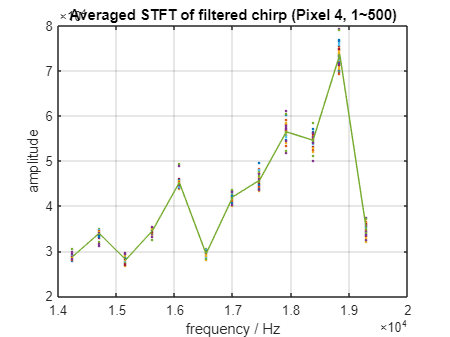

device = mi6;
ss_spec_mean = zeros(12, 9);
ss_amp_mean = zeros(length(freq), 1);
figure
for i = r
    % prepare data
    rr = start_list{device}(i); % 1:500 (end not included)
    signal_duration = 500 - 1;
    signal_filtered = data_filtered{device}(rr : rr+signal_duration);

    % stft
    n_window = 96;
    n_overlap = 48;
    n_fft = 96;
    [ss,ff,tt] = stft(signal_filtered, fs, 'Window', tukeywin(n_window,0.25), ...
        'OverlapLength', n_overlap, 'FFTLength', n_fft, 'FrequencyRange', 'onesided');

    f0 = 15000;
    f1 = 20000;
    segment = (fs/2) / n_overlap;
    lower_f = int8(f0/segment) - 1;
    upper_f = int8(f1/segment);
    ff = ff(lower_f:upper_f-1);
    ss = ss(lower_f:upper_f - 1,:); % end is included in MATLAB
    S = abs(ss) / max(max(abs(ss)));
    I = mat2gray(S);

%     figure
%     imagesc(tt * 170, ff / 1000, I); % distance as x-axis
%     xlabel('distance / m'); ylabel('frequency / kHz');
%     % imagesc(tt * 1000, ff / 1000, I); % time as x-axis
%     % xlabel('time / ms'); ylabel('frequency / kHz');
% 
%     title("Spectrogram (STFT) of Filtered Signal (550~2919)")
%     set(gca, 'YDir', 'normal');
%     colormap('hot')
    
    ss_sum = sum(abs(ss), 2);
    plot(freq, ss_sum, '.')
    title("Averaged STFT of filtered chirp (Pixel 4, 1~500)")
    xlabel("frequency / Hz"); ylabel("amplitude")
    hold on
    grid on

    ss_amp_mean = ss_amp_mean + ss_sum;
    ss_spec_mean = ss_spec_mean + abs(ss);
end
hold on
plot(freq, ss_amp_mean / length(r))

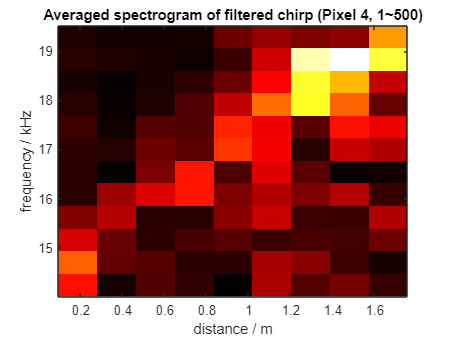


figure
S = abs(ss_spec_mean) / max(max(abs(ss_spec_mean)));
I = mat2gray(S);
imagesc(tt * 170, ff / 1000, I); % distance as x-axis
xlabel('distance / m'); ylabel('frequency / kHz');
% imagesc(tt * 1000, ff / 1000, I); % time as x-axis
% xlabel('time / ms'); ylabel('frequency / kHz');

title("Averaged spectrogram of filtered chirp (Pixel 4, 1~500)")
set(gca, 'YDir', 'normal');
colormap('hot')


frc_3 = ss_amp_mean / length(r);

#### Compare frc 2 and 3

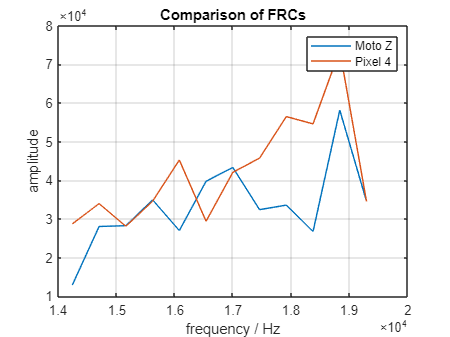

figure
plot(freq, frc_2)
hold on
grid on
plot(freq, frc_3)
title("Comparison of FRCs")
xlabel("frequency / Hz"); ylabel("amplitude")
legend("Moto Z", "Pixel 4")

margin = 0.1;
for i = 1:length(freq)
    if abs(frc_3(i)-frc_2(i))/frc_2(i) > margin
        weights_3(i) = min(weights_3(i) * frc_2(i)/frc_3(i), 1.0);
    end
end
disp(weights_3)

    0.0002    0.0007    0.2521
    0.2274    0.2383    0.4897
    0.0253    0.1454    0.0387
    0.1136    0.5596    0.3094

